# **InverseJacobiSN**

[Inverse of the Jacobi elliptic function sn](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{sn}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(x\left|m\right.\right) & m\le 1\\
\frac{{\textrm{sn}}^{-1} \left(x\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{sn}}^{-1} \left(x,k\right)\equiv {\mathrm{sn}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  the Jacobi  form of the elliptic integral of the first kind.

Domain: If $-\infty <m\le 1$ (or $|k|\le 1$) then $-1\le x\le 1$. If $m>1$ (or $k>1$)  then  $|x|<1/\sqrt{m}$. For the specified domain, the  codomain  is the set of real numbers.

Basic features:

${\mathrm{sn}}^{-1} \left(-x\left|m\right.\right)=-{\mathrm{sn}}^{-1} \left(x\left|m\right.\right)$   (odd)

Special values:

${\mathrm{sn}}^{-1} \left(0\left|m\right.\right)=0$,   ${\mathrm{sn}}^{-1} \left(1\left|m\right.\right)=K\left(m\right)$

${\mathrm{sn}}^{-1} \left(x\left|-\infty \right.\right)=0$,   ${\mathrm{sn}}^{-1} \left(x\left|0\right.\right)=\sin^{-1} \left(x\right)$,   ${\mathrm{sn}}^{-1} \left(x\left|1\right.\right)={\textrm{tanh}}^{-1} \left(x\right)$

Identities:


$${\mathrm{sn}}^{-1} \left(\mathrm{sn}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{sn}\;\left({\textrm{sn}}^{-1} \left(x\left|m\right.\right)\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind .

## Syntax

Y = InverseJacobiSN(X,K)

y = ijsn(x,k)

Y = mInverseJacobiSN(X,M)

y = mijsn(x,m)

**Note. **InverseJacobiSN is equal to the function EllipticF

## Description

**Y = InverseJacobiSN(X,K)** return the Jacobi form of elliptic integral of the first kind ${\mathrm{sn}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **InverseJacobiSN** is the wrapper function which calls the functions **ijsn** element-wise via the function **ufun2**.

**y = ijsn(x,k)** return the value of the Jacobi form of elliptic integral of the first kind  ${\mathrm{sn}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. ijsn is the wrapper function which calls the functions **mijsn**.

**Y = mInverseJacobiSN(X,M)** returns the Jacobi form of elliptic integral of the first kind ${\mathrm{sn}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mInverseJacobiSN** is the wrapper function which calls the functions mijsn element-wise via the function **ufun2**.

**y = mijsn(x,m)** compute value of the Jacobi form of elliptic integral of the first kind  ${\mathrm{sn}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijsn **call the Carlson's function **rf **for calculation of ${\mathrm{sn}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[ijsn(x,k), InverseJacobiSN(x,k), mijsn(x,k^2), mInverseJacobiSN(x,k^2)]

ans =    0.529428627051906   0.529428627051906   0.529428627051906   0.529428627051906


Accuracy.

fprintf('%.16g\n',ijsn(0.5,1.2)) 

0.5631345956371008


%  Maple 0.5631345956371007_23

Special values

m = -2;
x = -0.5;  % |x| <= 1
mijsn(0,m)

ans = 0

disp(mijsn(1,m) - melK(m))  % m < 1 !!!

     0



mijsn(x,-inf)

ans = 0

disp(mijsn(x,0) - asin(x)) 

     0



disp(mijsn(x,1) - atanh(x))

     0



mijsn(x,inf)  % x = 0

ans = NaN

Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mInverseJacobiSN(-x,m) + mInverseJacobiSN(x,m))

     0



disp(mInverseJacobiSN(x,m) - mpEllipticF(asin(x),m))

    -1.665334536937735e-16



k = 0.99995;
disp(InverseJacobiSN(1/sqrt(1+sqrt(1-k^2)),k)-elK(k)/2)

     2.309263891220326e-13



**Vector input**

k = [0.1, 0.5, 0.89, 0.99995];
disp(InverseJacobiSN(1./sqrt(1+sqrt(1-k.^2)),k)-EllipticK(k)/2)

   1.0e-12 *

                   0                   0  -0.000222044604925   0.230926389122033



**Matrix input**

k = [0.1, 0.5, 0.89; -0.1, -0.97, 0.99995 ]';
disp(InverseJacobiSN(1./sqrt(1+sqrt(1-k.^2)),k)-EllipticK(k)/2)

   1.0e-12 *

                   0                   0
                   0  -0.000444089209850
  -0.000222044604925   0.230926389122033



## **Plot **

**Example 1**

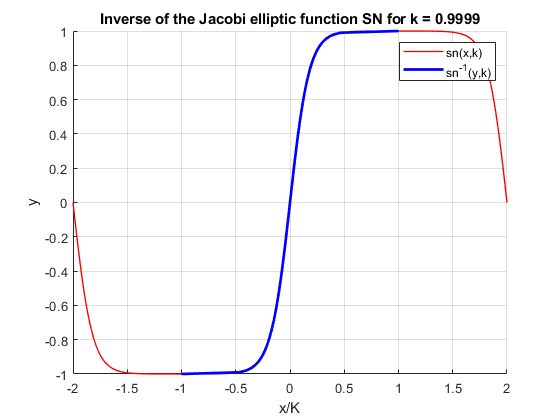

figure
hold on
x=-2:0.01:2;
k = 0.9999;
K = elK(k);
plot(x,JacobiSN(K*x,k),'LineWidth',1.0,'Color','red')
x=-1:0.01:1;
plot(InverseJacobiSN(x,k)/K,x,'LineWidth',2,'Color','blue')
legend('sn(x,k)','sn^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function SN for k = %g',k))
grid on
hold off

**Example 2**

figure
X = -1:0.001:1;
M = [-10,-1,0,1,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiSN(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -3 3])
grid on
legend(clg,'Location','Best')

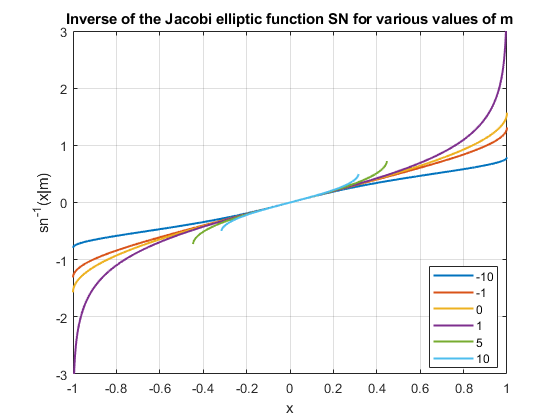

title('Inverse of the Jacobi elliptic function SN for various values of m')
xlabel('x')
ylabel('sn^{-1}(x|m)')

**Example 3**

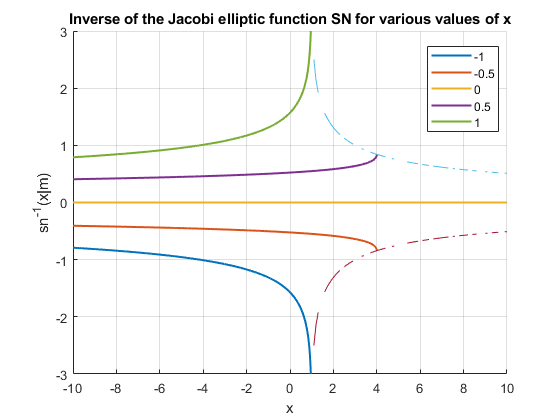

figure
hold on
M = -10:0.01:10;
X = [-1,-0.5,0,0.5,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiSN(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function SN for various values of x')
xlabel('x')
ylabel('sn^{-1}(x|m)')
M = 0:0.1:10;
F = mInverseJacobiSN(1./sqrt(abs(M)),M);
plot(M,F)
plot(M,-F)
hold off

**Example 4**

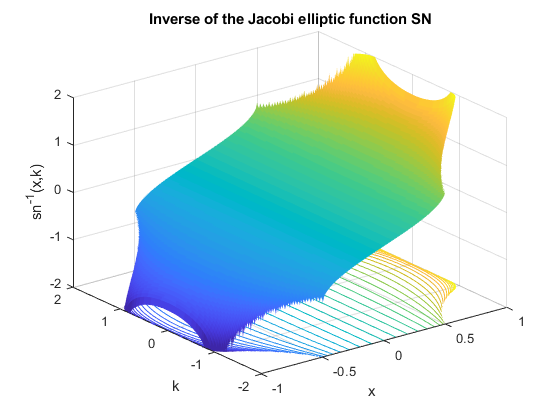

figure
x=-1:0.01:1;
k=-2:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,InverseJacobiSN(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
caxis([-2 2])
view(3);
xlabel('x')
ylabel('k')
zlabel('sn^{-1}(x,k)')
title('Inverse of the Jacobi elliptic function SN')
zlim([-2 2])
grid on

**Example 5**

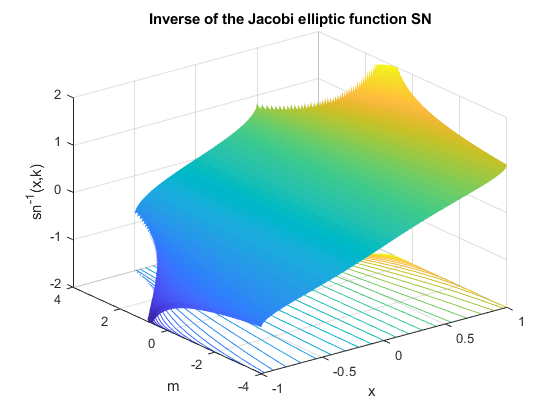

figure
x=-1:0.01:1;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiSN(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
view(3)
caxis([-2 2])
xlabel('x')
ylabel('m')
zlabel('sn^{-1}(x,k)')
title('Inverse of the Jacobi elliptic function SN')
zlim([-2 2])
grid on

**Example 6**

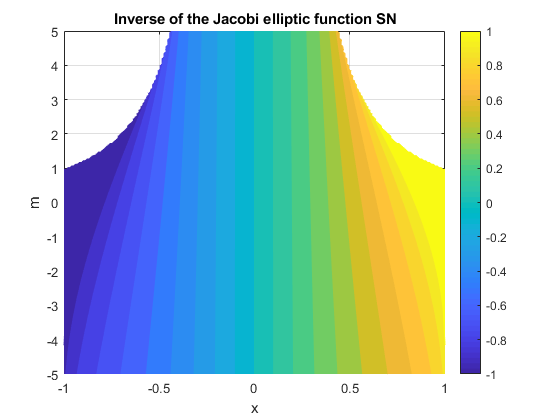

figure
f = @(x,m)mInverseJacobiSN(x,m);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Inverse of the Jacobi elliptic function SN')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 7**

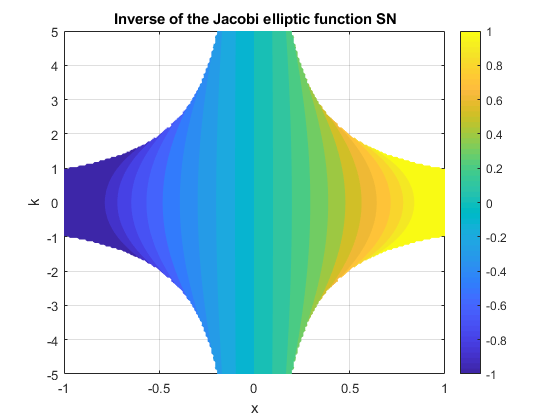

figure
f = @(x,k)InverseJacobiSN(x,k);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Inverse of the Jacobi elliptic function SN')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also